csv = readtable("Cyclic_avg_sd_NorthernHemisphere.csv","VariableNamingRule","preserve");

month_fraction = csv{1:392,1};
month_all = csv{1:392,3};
country_all = csv{1:392,5};
size_all = csv{1:392,6};
toughness_all = csv{1:392,7};
youngsm_all = csv{1:392,9};
strength_all = csv{1:392,11};
strain_all = csv{1:392,13};
onepercent_all = csv{1:392,15};
fivepercent_all = csv{1:392,16};
tenpercent_all = csv{1:392,17};
crystallinity_all = csv{1:392,18};
birefringence_all = csv{1:392,19};
diameter_all = csv{1:392,21};
watercontent_all = csv{1:392,23};
supercontraction_all = csv{1:392,24};

month_names = csv{1:392,27};
month = csv{1:12,28};

toughness_avg = csv{1:12,29};
youngsm_avg = csv{1:12,31};
strength_avg = csv{1:12,33};
strain_avg = csv{1:12,35};
onepercent_avg = csv{1:12,37};
fivepercent_avg = csv{1:12,39};
tenpercent_avg = csv{1:12,41};
crystallinity_avg = csv{1:12,43};
birefringence_avg = csv{1:12,45};
diameter_avg = csv{1:12,47};
watercontent_avg = csv{1:12,49};
supercontraction_avg = csv{1:12,51};

toughness_sd = csv{1:12,30};
youngsm_sd = csv{1:12,32};
strength_sd = csv{1:12,34};
strain_sd = csv{1:12,36};
onepercent_sd = csv{1:12,38};
fivepercent_sd = csv{1:12,40};
tenpercent_sd = csv{1:12,42};
crystallinity_sd = csv{1:12,44};
birefringence_sd = csv{1:12,46};
diameter_sd = csv{1:12,48};
watercontent_sd = csv{1:12,50};
supercontraction_sd = csv{1:12,52};

props = [toughness_all, youngsm_all, strength_all, strain_all, onepercent_all, fivepercent_all, tenpercent_all, ...
    crystallinity_all, birefringence_all, diameter_all, watercontent_all, supercontraction_all];
prop_labels = ["Toughness", "Young''s Modulus", "Strength", "Strain", "1% Weightloss", "5% Weightloss", "10% Weightloss", ...
    "Crystallinity", "Birefringence", "Diameter", "Watercontent", "Supercontraction"];

prop_labels = 1×12 string array
    "Toughness"    "Young''s Modulus"    "Strength"    "Strain"    "1% Weightloss"    "5% Weightloss"    "10% Weightloss"    "Crystallinity"    "Birefringence"    "Diameter"    "Watercontent"    "Supercontraction"


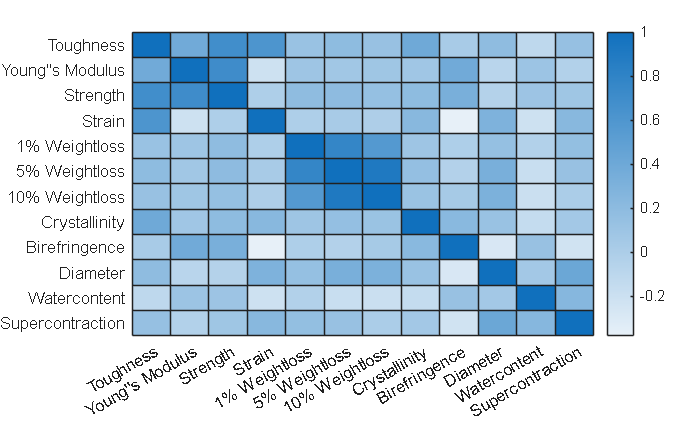


pearson_corr = corrcoef(props,'Rows','complete');
% plotmatrix(props)
heatmap(pearson_corr,'YDisplayLabel',prop_labels,'XDisplayLabels',prop_labels)

% toughness

a = 0.0025;
b = 0.106;
r = 0.0085;
s = 1.7691;
t = 0.1252;

Title = 'Toughness (GJ m^{-3})';
all = toughness_all;
avg = toughness_avg;

				
linear_fit = a * month + b;
sine_fit = r * sin(0.5712*month+s)+t;

linear_residual = avg - linear_fit;
sine_residual = avg - sine_fit;


%% PLOT 
subplot(3,1,1);
scatter(month_all,all,'marker','.','MarkerEdgeColor','black')
% simple_violin_scatter(month_all, all, 1, 0.5,{'marker','.','MarkerEdgeColor','black'})
hold on
% violinplot(month_all, all,'FaceColor', 'black')
xlim([0.75 12.25])
title(Title)
box on
hold off

subplot(3,1,2); 
scatter(month,avg,'Marker','o','MarkerEdgeColor','black')
hold on
plot(month, linear_fit, 'Color', 'g');
plot(month, sine_fit, 'Color', 'b');
xlim([0.75 12.25])
box on
hold off

subplot(3,1,3);
stem(month,linear_residual, 'Color', 'g')
hold on
stem(month,sine_residual, 'Color', 'b')
yline(0)
xlim([0.75 12.25])
xlabel('Month')
box on
hold off	

% youngsm

a = 0.2945;
b = 6.6809;
r = -1.7934;
s = 0.5305;
t = 8.2901;

Title = 'Young''s Modulus (GPa)';
all = youngsm_all;
avg = youngsm_avg;

				
linear_fit = a * month + b;
sine_fit = r * sin(0.5712*month+s)+t;

linear_residual = avg - linear_fit;
sine_residual = avg - sine_fit;


%% PLOT 
subplot(3,1,1);
scatter(month_all,all,'marker','.','MarkerEdgeColor','black')
% simple_violin_scatter(month_all, all, 1, 0.5,{'marker','.','MarkerEdgeColor','black'})
hold on
% violinplot(month_all, all,'FaceColor', 'black')
xlim([0.75 12.25])
title(Title)
box on
hold off

subplot(3,1,2); 
scatter(month,avg,'Marker','o','MarkerEdgeColor','black')
hold on
plot(month, linear_fit, 'Color', 'g');
plot(month, sine_fit, 'Color', 'b');
xlim([0.75 12.25])
box on
hold off

subplot(3,1,3);
stem(month,linear_residual, 'Color', 'g')
hold on
stem(month,sine_residual, 'Color', 'b')
yline(0)
xlim([0.75 12.25])
xlabel('Month')
box on
hold off	

% strength

a = 0.0087;
b = 1.0936;
r = -0.0633;
s = 0.9341;
t = 1.1389;

Title = 'Tensile Strength (GPa)';
all = strength_all;
avg = strength_avg;
				
linear_fit = a * month + b;
sine_fit = r * sin(0.5712*month+s)+t;

linear_residual = avg - linear_fit;
sine_residual = avg - sine_fit;


%% PLOT 
subplot(3,1,1);
scatter(month_all,all,'marker','.','MarkerEdgeColor','black')
hold on
xlim([0.75 12.25])
title(Title)
box on
hold off

subplot(3,1,2); 
scatter(month,avg,'Marker','o','MarkerEdgeColor','black')
hold on
plot(month, linear_fit, 'Color', 'g');
plot(month, sine_fit, 'Color', 'b');
xlim([0.75 12.25])
box on
hold off

subplot(3,1,3);
stem(month,linear_residual, 'Color', 'g')
hold on
stem(month,sine_residual, 'Color', 'b')
yline(0)
xlim([0.75 12.25])
xlabel('Month')
box on
hold off	

% strain

a = 0.0706;
b = 20.198;
r = 2.4734;
s = 1.0858;
t = 21.325;

Title = 'Strain at Break (%)';
all = strain_all;
avg = strain_avg;

				
linear_fit = a * month + b;
sine_fit = r * sin(0.5712*month+s)+t;

linear_residual = avg - linear_fit;
sine_residual = avg - sine_fit;


%% PLOT 
subplot(3,1,1);
scatter(month_all,all,'marker','.','MarkerEdgeColor','black')
% simple_violin_scatter(month_all, all, 1, 0.5,{'marker','.','MarkerEdgeColor','black'})
hold on
% violinplot(month_all, all,'FaceColor', 'black')
xlim([0.75 12.25])
title(Title)
box on
hold off

subplot(3,1,2); 
scatter(month,avg,'Marker','o','MarkerEdgeColor','black')
hold on
plot(month, linear_fit, 'Color', 'g');
plot(month, sine_fit, 'Color', 'b');
xlim([0.75 12.25])
box on
hold off

subplot(3,1,3);
stem(month,linear_residual, 'Color', 'g')
hold on
stem(month,sine_residual, 'Color', 'b')
yline(0)
xlim([0.75 12.25])
xlabel('Month')
box on
hold off	

% onepercent

a = -0.7418;
b = 230.28;
r = 4.0127;
s = -0.7089;
t = 225.43;

Title = '1% weight loss (^\circ C)';
all = onepercent_all;
avg = onepercent_avg;

				
linear_fit = a * month + b;
sine_fit = r * sin(0.5712*month+s)+t;

linear_residual = avg - linear_fit;
sine_residual = avg - sine_fit;


%% PLOT 
subplot(3,1,1);
scatter(month_all,all,'marker','.','MarkerEdgeColor','black')
% simple_violin_scatter(month_all, all, 1, 0.5,{'marker','.','MarkerEdgeColor','black'})
hold on
% violinplot(month_all, all,'FaceColor', 'black')
xlim([0.75 12.25])
title(Title)
box on
hold off

subplot(3,1,2); 
scatter(month,avg,'Marker','o','MarkerEdgeColor','black')
hold on
plot(month, linear_fit, 'Color', 'g');
plot(month, sine_fit, 'Color', 'b');
xlim([0.75 12.25])
box on
hold off

subplot(3,1,3);
stem(month,linear_residual, 'Color', 'g')
hold on
stem(month,sine_residual, 'Color', 'b')
yline(0)
xlim([0.75 12.25])
xlabel('Month')
box on
hold off	

% fivepercent

a = -0.3821;
b = 279.21;
r = 1.1924;
s = 35.969;
t = 276.19;

Title = '5% weight loss (^\circ C)';
all = fivepercent_all;
avg = fivepercent_avg;
				
linear_fit = a * month + b;
sine_fit = r * sin(0.5712*month+s)+t;

linear_residual = avg - linear_fit;
sine_residual = avg - sine_fit;


%% PLOT 
subplot(3,1,1);
scatter(month_all,all,'marker','.','MarkerEdgeColor','black')
% simple_violin_scatter(month_all, all, 1, 0.5,{'marker','.','MarkerEdgeColor','black'})
hold on
% violinplot(month_all, all,'FaceColor', 'black')
xlim([0.75 12.25])
title(Title)
box on
hold off

subplot(3,1,2); 
scatter(month,avg,'Marker','o','MarkerEdgeColor','black')
hold on
plot(month, linear_fit, 'Color', 'g');
plot(month, sine_fit, 'Color', 'b');
xlim([0.75 12.25])
box on
hold off

subplot(3,1,3);
stem(month,linear_residual, 'Color', 'g')
hold on
stem(month,sine_residual, 'Color', 'b')
yline(0)
xlim([0.75 12.25])
xlabel('Month')
box on
hold off	

% tenpercent

a = -0.1212;
b = 299.44;
r = -0.5762;
s = -19.367;
t = 298.42;

Title = '10% weight loss (^\circ C)';
all = tenpercent_all;
avg = tenpercent_avg;

				
linear_fit = a * month + b;
sine_fit = r * sin(0.5712*month+s)+t;

linear_residual = avg - linear_fit;
sine_residual = avg - sine_fit;


%% PLOT 
subplot(3,1,1);
scatter(month_all,all,'marker','.','MarkerEdgeColor','black')
% simple_violin_scatter(month_all, all, 1, 0.5,{'marker','.','MarkerEdgeColor','black'})
hold on
% violinplot(month_all, all,'FaceColor', 'black')
xlim([0.75 12.25])
title(Title)
box on
hold off

subplot(3,1,2); 
scatter(month,avg,'Marker','o','MarkerEdgeColor','black')
hold on
plot(month, linear_fit, 'Color', 'g');
plot(month, sine_fit, 'Color', 'b');
xlim([0.75 12.25])
box on
hold off

subplot(3,1,3);
stem(month,linear_residual, 'Color', 'g')
hold on
stem(month,sine_residual, 'Color', 'b')
yline(0)
xlim([0.75 12.25])
xlabel('Month')
box on
hold off	

% crystallinity

a = 1.0719;
b = 11.42;
r = -4.93;
s = -0.6597;
t = 18.55;

Title = 'Degree of Crystallinity (%)';
all = crystallinity_all;
avg = crystallinity_avg;

				
linear_fit = a * month + b;
sine_fit = r * sin(0.5712*month+s)+t;

linear_residual = avg - linear_fit;
sine_residual = avg - sine_fit;


%% PLOT 
subplot(3,1,1);
scatter(month_all,all,'marker','.','MarkerEdgeColor','black','ColorVariable','country_all')
% simple_violin_scatter(month_all, all, 1, 0.5,{'marker','.','MarkerEdgeColor','black'})
hold on
% violinplot(month_all, all,'FaceColor', 'black')
xlim([0.75 12.25])
title(Title)
box on
hold off

subplot(3,1,2); 
scatter(month,avg,'Marker','o','MarkerEdgeColor','black')
hold on
plot(month, linear_fit, 'Color', 'g');
plot(month, sine_fit, 'Color', 'b');
xlim([0.75 12.25])
box on
hold off

subplot(3,1,3);
stem(month,linear_residual, 'Color', 'g')
hold on
stem(month,sine_residual, 'Color', 'b')
yline(0)
xlim([0.75 12.25])
xlabel('Month')
box on
hold off	

% birefringence

a = -0.054;
b = 46.273;
r = -1.6995;
s = 4.0655;
t = 46.349;

Title = 'Birefringence (\times 10^{-3})';
all = birefringence_all;
avg = birefringence_avg;

				
linear_fit = a * month + b;
sine_fit = r * sin(0.5712*month+s)+t;

linear_residual = avg - linear_fit;
sine_residual = avg - sine_fit;


%% PLOT 
subplot(3,1,1);
scatter(month_all,all,'marker','.','MarkerEdgeColor','black')
% simple_violin_scatter(month_all, all, 1, 0.5,{'marker','.','MarkerEdgeColor','black'})
hold on
% violinplot(month_all, all,'FaceColor', 'black')
xlim([0.75 12.25])
title(Title)
box on
hold off

subplot(3,1,2); 
scatter(month,avg,'Marker','o','MarkerEdgeColor','black')
hold on
plot(month, linear_fit, 'Color', 'g');
plot(month, sine_fit, 'Color', 'b');
xlim([0.75 12.25])
legend('Average Value','Linear Fit','Sinusoidal Fit','Location','bestoutside')
box on
hold off

subplot(3,1,3);
stem(month,linear_residual, 'Color', 'g')
hold on
stem(month,sine_residual, 'Color', 'b')
yline(0)
xlim([0.75 12.25])
xlabel('Month')
legend('Linear Residuals','Sinusoidal Residuals','Location','bestoutside')
box on
hold off	

% diameter

a = 0.037;
b = 1.166;
r = 0.1969;
s = -10.31;
t = 1.4278;

Title = 'Diameter (\mu M)';
all = diameter_all;
avg = diameter_avg;

				
linear_fit = a * month + b;
sine_fit = r * sin(0.5712*month+s)+t;

linear_residual = avg - linear_fit;
sine_residual = avg - sine_fit;


%% PLOT 
subplot(3,1,1);
scatter(month_all,all,'marker','.','MarkerEdgeColor','black')
% simple_violin_scatter(month_all, all, 1, 0.5,{'marker','.','MarkerEdgeColor','black'})
hold on
% violinplot(month_all, all,'FaceColor', 'black')
xlim([0.75 12.25])
title(Title)
box on
hold off

subplot(3,1,2); 
scatter(month,avg,'Marker','o','MarkerEdgeColor','black')
hold on
plot(month, linear_fit, 'Color', 'g');
plot(month, sine_fit, 'Color', 'b');
xlim([0.75 12.25])
box on
hold off

subplot(3,1,3);
stem(month,linear_residual, 'Color', 'g')
hold on
stem(month,sine_residual, 'Color', 'b')
yline(0)
xlim([0.75 12.25])
xlabel('Month')
box on
hold off	

% watercontent

a = -0.1458;
b = 8.1048;
r = 0.9073;
s = -1.112;
t = 7.0491;

Title = 'Water content (%)';
all = watercontent_all;
avg = watercontent_avg;

				
linear_fit = a * month + b;
sine_fit = r * sin(0.5712*month+s)+t;

linear_residual = avg - linear_fit;
sine_residual = avg - sine_fit;


%% PLOT 
subplot(3,1,1);
scatter(month_all,all,'marker','.','MarkerEdgeColor','black')
% simple_violin_scatter(month_all, all, 1, 0.5,{'marker','.','MarkerEdgeColor','black'})
hold on
% violinplot(month_all, all,'FaceColor', 'black')
xlim([0.75 12.25])
title(Title)
box on
hold off

subplot(3,1,2); 
scatter(month,avg,'Marker','o','MarkerEdgeColor','black')
hold on
plot(month, linear_fit, 'Color', 'g');
plot(month, sine_fit, 'Color', 'b');
xlim([0.75 12.25])
box on
hold off

subplot(3,1,3);
stem(month,linear_residual, 'Color', 'g')
hold on
stem(month,sine_residual, 'Color', 'b')
yline(0)
xlim([0.75 12.25])
xlabel('Month')
box on
hold off	

% supercontraction

a = 0.4803;
b = 26.03;
r = -5.4368;
s = 0.907;
t = 28.753;

Title = 'Supercontraction (%)';
all = supercontraction_all;
avg = supercontraction_avg;

				
linear_fit = a * month + b;
sine_fit = r * sin(0.5712*month+s)+t;

linear_residual = avg - linear_fit;
sine_residual = avg - sine_fit;


%% PLOT 
subplot(3,1,1);
scatter(month_all,all,'marker','.','MarkerEdgeColor','black')
% simple_violin_scatter(month_all, all, 1, 0.5,{'marker','.','MarkerEdgeColor','black'})
hold on
% violinplot(month_all, all,'FaceColor', 'black')
xlim([0.75 12.25])
title(Title)
box on
hold off

subplot(3,1,2); 
scatter(month,avg,'Marker','o','MarkerEdgeColor','black')
hold on
plot(month, linear_fit, 'Color', 'g');
plot(month, sine_fit, 'Color', 'b');
xlim([0.75 12.25])
box on
hold off

subplot(3,1,3);
stem(month,linear_residual, 'Color', 'g')
hold on
stem(month,sine_residual, 'Color', 'b')
yline(0)
xlim([0.75 12.25])
xlabel('Month')
box on
hold off

csv_Aus = readtable("cyclic_avg_sd_AusOnly.csv","VariableNamingRule","preserve");

month_fraction_Aus = csv_Aus{1:29,1};
month_all_Aus = csv_Aus{1:29,3};
country_all_Aus = csv_Aus{1:29,5};
size_all_Aus = csv_Aus{1:29,6};
toughness_all_Aus = csv_Aus{1:29,7};
youngsm_all_Aus = csv_Aus{1:29,9};
strength_all_Aus = csv_Aus{1:29,11};
strain_all_Aus = csv_Aus{1:29,13};
onepercent_all_Aus = csv_Aus{1:29,15};
fivepercent_all_Aus = csv_Aus{1:29,16};
tenpercent_all_Aus = csv_Aus{1:29,17};
crystallinity_all_Aus = csv_Aus{1:29,18};
birefringence_all_Aus = csv_Aus{1:29,19};
diameter_all_Aus = csv_Aus{1:29,21};
watercontent_all_Aus = csv_Aus{1:29,23};
supercontraction_all_Aus = csv_Aus{1:29,24};

month_names_Aus = csv_Aus{1:29,27};
month_Aus = csv_Aus{1:2,28};

toughness_avg_Aus = csv_Aus{1:2,29};
youngsm_avg_Aus = csv_Aus{1:2,31};
strength_avg_Aus = csv_Aus{1:2,33};
strain_avg_Aus = csv_Aus{1:2,35};
onepercent_avg_Aus = csv_Aus{1:2,37};
fivepercent_avg_Aus = csv_Aus{1:2,39};
tenpercent_avg_Aus = csv_Aus{1:2,41};
crystallinity_avg_Aus = csv_Aus{1:2,43};
birefringence_avg_Aus = csv_Aus{1:2,45};
diameter_avg_Aus = csv_Aus{1:2,47};
watercontent_avg_Aus = csv_Aus{1:2,49};
supercontraction_avg_Aus = csv_Aus{1:2,51};

toughness_sd_Aus = csv_Aus{1:2,30};
youngsm_sd_Aus = csv_Aus{1:2,32};
strength_sd_Aus = csv_Aus{1:2,34};
strain_sd_Aus = csv_Aus{1:2,36};
onepercent_sd_Aus = csv_Aus{1:2,38};
fivepercent_sd_Aus = csv_Aus{1:2,40};
tenpercent_sd_Aus = csv_Aus{1:2,42};
crystallinity_sd_Aus = csv_Aus{1:2,44};
birefringence_sd_Aus = csv_Aus{1:2,46};
diameter_sd_Aus = csv_Aus{1:2,48};
watercontent_sd_Aus = csv_Aus{1:2,50};
supercontraction_sd_Aus = csv_Aus{1:2,52};

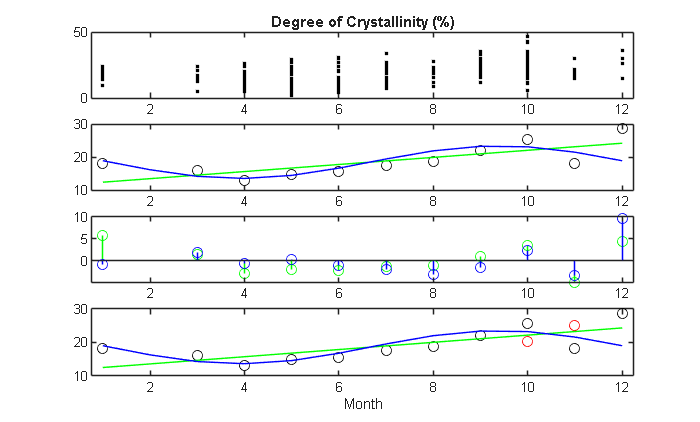

% toughness

a = 0.0025;
b = 0.106;
r = 0.0085;
s = 1.7691;
t = 0.1252;

Title = 'Toughness (GJ m^{-3})';
all = toughness_all;
avg = toughness_avg;
avg_aus = toughness_avg_Aus;
				
linear_fit = a * month + b;
sine_fit = r * sin(0.5712*month+s)+t;

linear_residual = avg - linear_fit;
sine_residual = avg - sine_fit;


%% PLOT 
subplot(4,1,1);

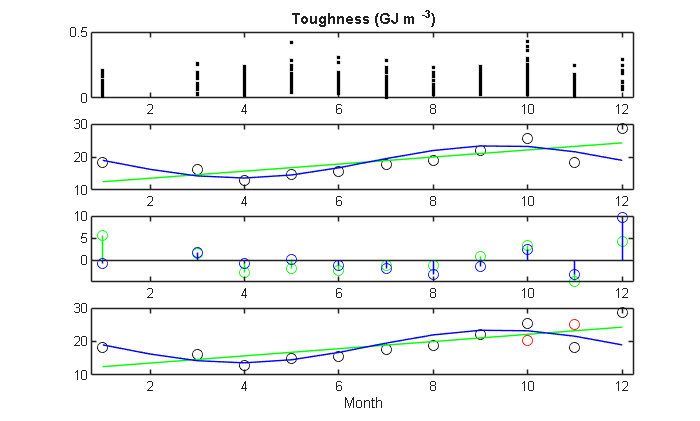

scatter(month_all,all,'marker','.','MarkerEdgeColor','black')
% simple_violin_scatter(month_all, all, 1, 0.5,{'marker','.','MarkerEdgeColor','black'})
hold on
% violinplot(month_all, all,'FaceColor', 'black')
xlim([0.75 12.25])
title(Title)
box on
hold off

subplot(4,1,2); 

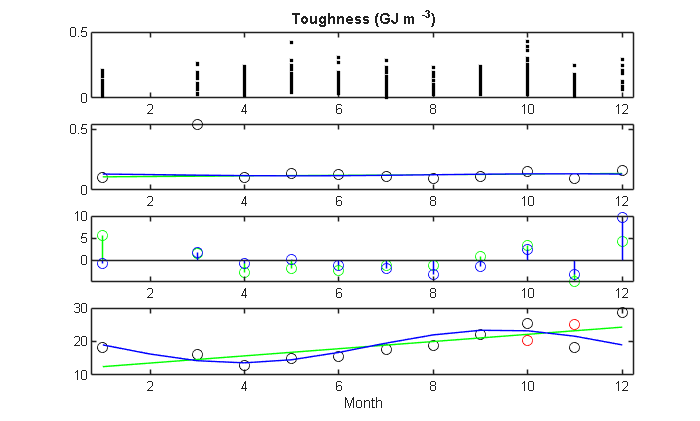

scatter(month,avg,'Marker','o','MarkerEdgeColor','black')
hold on
plot(month, linear_fit, 'Color', 'g');
plot(month, sine_fit, 'Color', 'b');
xlim([0.75 12.25])
box on
hold off

subplot(4,1,3);

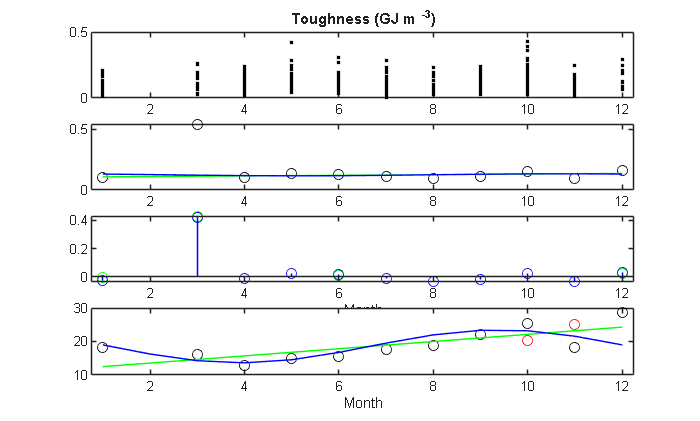

stem(month,linear_residual, 'Color', 'g')
hold on
stem(month,sine_residual, 'Color', 'b')
yline(0)
xlim([0.75 12.25])
xlabel('Month')
box on
hold off		

subplot(4,1,4); 

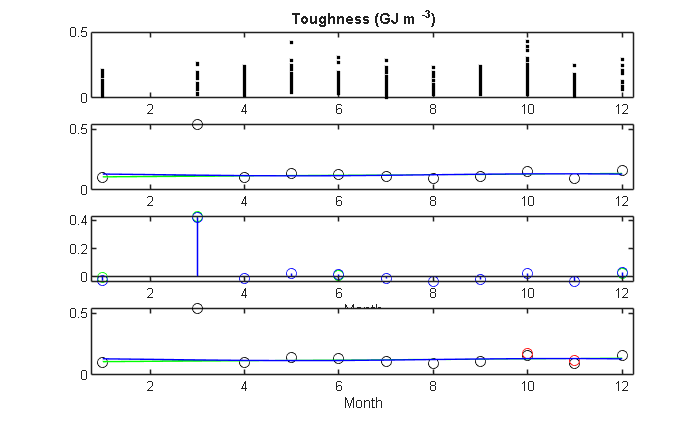

scatter(month,avg,'Marker','o','MarkerEdgeColor','black')
hold on
scatter(month_Aus,avg_aus,'Marker','o','MarkerEdgeColor','red')
plot(month, linear_fit, 'Color', 'g');
plot(month, sine_fit, 'Color', 'b');
xlim([0.75 12.25])
xlabel('Month')
box on
hold off

% youngsm

a = 0.2945;
b = 6.6809;
r = -1.7934;
s = 0.5305;
t = 8.2901;

Title = 'Young''s Modulus (GPa)';
all = youngsm_all;
avg = youngsm_avg;
avg_aus = youngsm_avg_Aus;
				
linear_fit = a * month + b;
sine_fit = r * sin(0.5712*month+s)+t;

linear_residual = avg - linear_fit;
sine_residual = avg - sine_fit;


%% PLOT 
subplot(4,1,1);

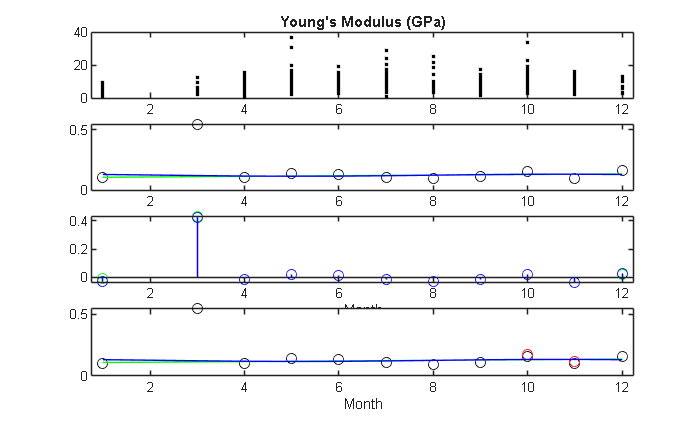

scatter(month_all,all,'marker','.','MarkerEdgeColor','black')
% simple_violin_scatter(month_all, all, 1, 0.5,{'marker','.','MarkerEdgeColor','black'})
hold on
% violinplot(month_all, all,'FaceColor', 'black')
xlim([0.75 12.25])
title(Title)
box on
hold off

subplot(4,1,2); 

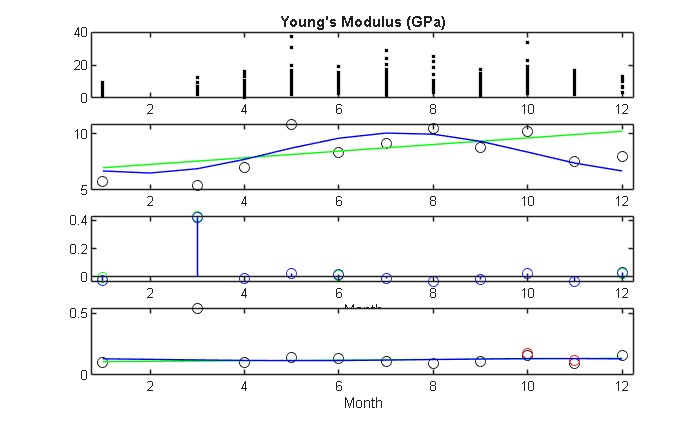

scatter(month,avg,'Marker','o','MarkerEdgeColor','black')
hold on
plot(month, linear_fit, 'Color', 'g');
plot(month, sine_fit, 'Color', 'b');
xlim([0.75 12.25])
box on
hold off

subplot(4,1,3);

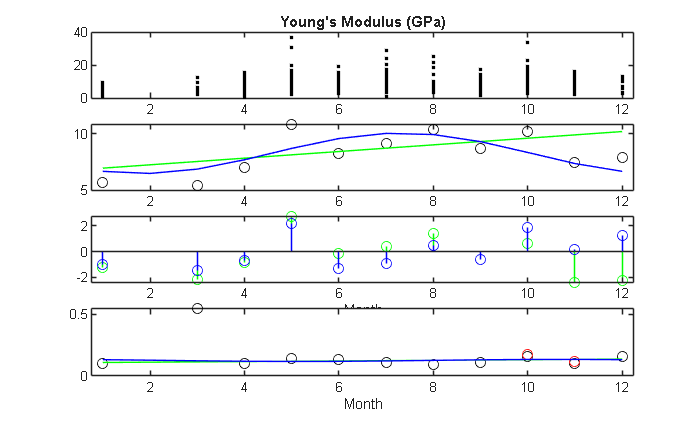

stem(month,linear_residual, 'Color', 'g')
hold on
stem(month,sine_residual, 'Color', 'b')
yline(0)
xlim([0.75 12.25])
xlabel('Month')
box on
hold off		

subplot(4,1,4); 

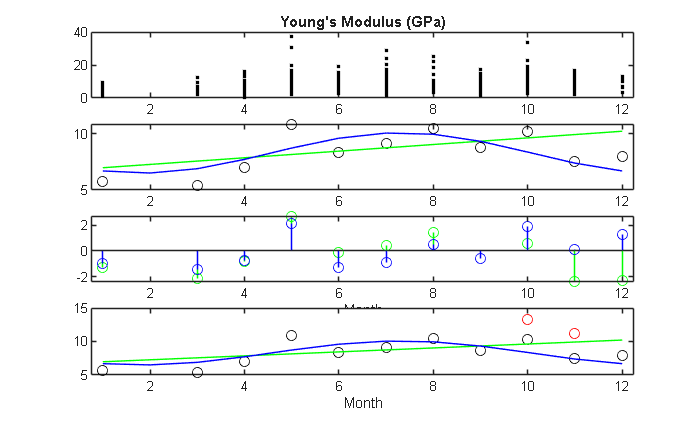

scatter(month,avg,'Marker','o','MarkerEdgeColor','black')
hold on
scatter(month_Aus,avg_aus,'Marker','o','MarkerEdgeColor','red')
plot(month, linear_fit, 'Color', 'g');
plot(month, sine_fit, 'Color', 'b');
xlim([0.75 12.25])
xlabel('Month')
box on
hold off

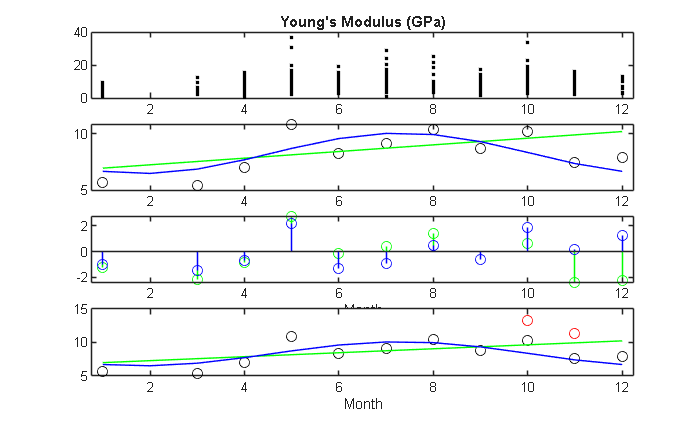

% strength

a = 0.0087;
b = 1.0936;
r = -0.0633;
s = 0.9341;
t = 1.1389;

Title = 'Tensile Strength (GPa)';
all = strength_all;
avg = strength_avg;
avg_aus = strength_avg_Aus;

linear_fit = a * month + b;
sine_fit = r * sin(0.5712*month+s)+t;

linear_residual = avg - linear_fit;
sine_residual = avg - sine_fit;


%% PLOT 
subplot(4,1,1);

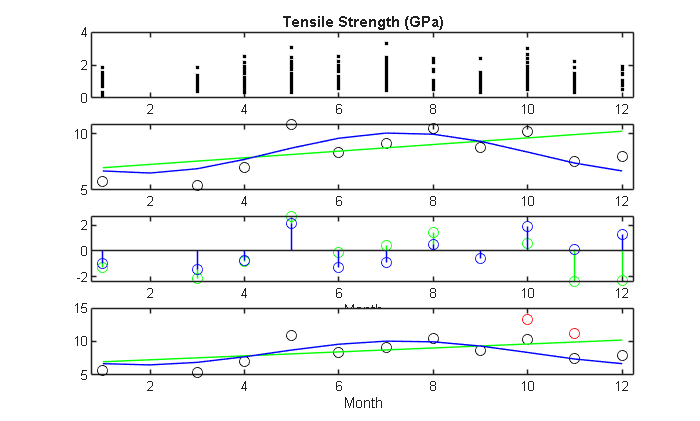

scatter(month_all,all,'marker','.','MarkerEdgeColor','black')
hold on
xlim([0.75 12.25])
title(Title)
box on
hold off

subplot(4,1,2); 

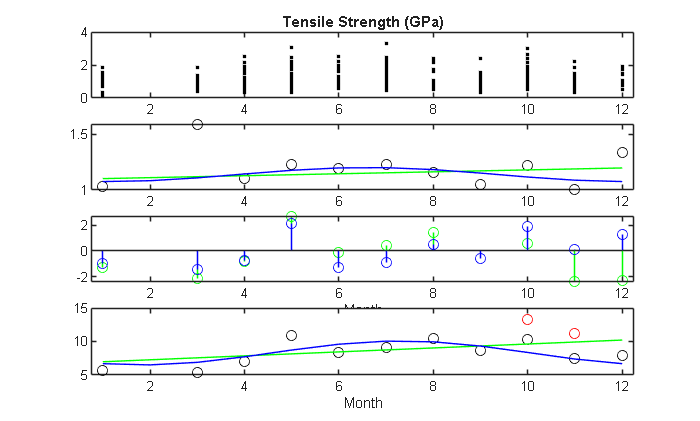

scatter(month,avg,'Marker','o','MarkerEdgeColor','black')
hold on
plot(month, linear_fit, 'Color', 'g');
plot(month, sine_fit, 'Color', 'b');
xlim([0.75 12.25])
box on
hold off

subplot(4,1,3);

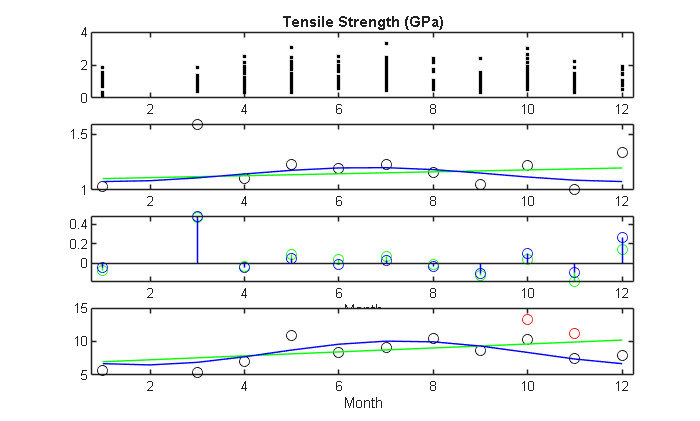

stem(month,linear_residual, 'Color', 'g')
hold on
stem(month,sine_residual, 'Color', 'b')
yline(0)
xlim([0.75 12.25])
xlabel('Month')
box on
hold off		

subplot(4,1,4); 

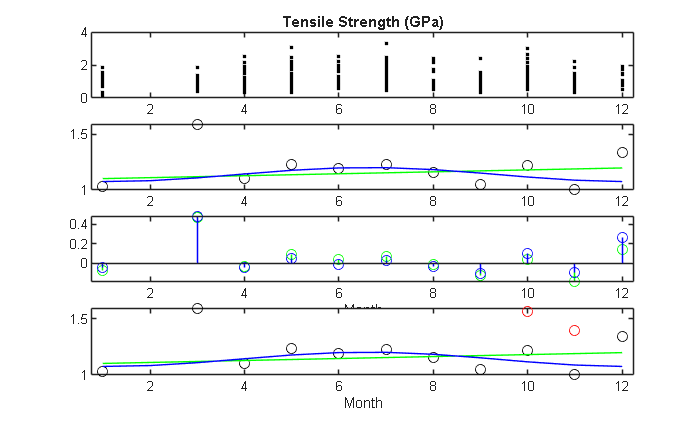

scatter(month,avg,'Marker','o','MarkerEdgeColor','black')
hold on
scatter(month_Aus,avg_aus,'Marker','o','MarkerEdgeColor','red')
plot(month, linear_fit, 'Color', 'g');
plot(month, sine_fit, 'Color', 'b');
xlim([0.75 12.25])
xlabel('Month')
box on
hold off

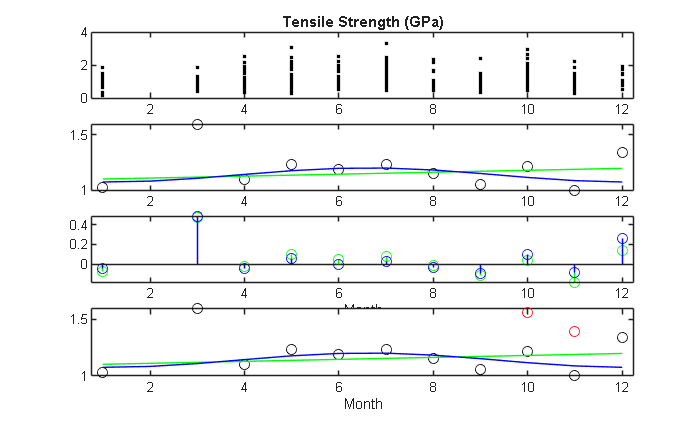

% strain

a = 0.0706;
b = 20.198;
r = 2.4734;
s = 1.0858;
t = 21.325;

Title = 'Strain at Break (%)';
all = strain_all;
avg = strain_avg;
avg_aus = strain_avg_Aus;

				
linear_fit = a * month + b;
sine_fit = r * sin(0.5712*month+s)+t;

linear_residual = avg - linear_fit;
sine_residual = avg - sine_fit;


%% PLOT 
subplot(4,1,1);

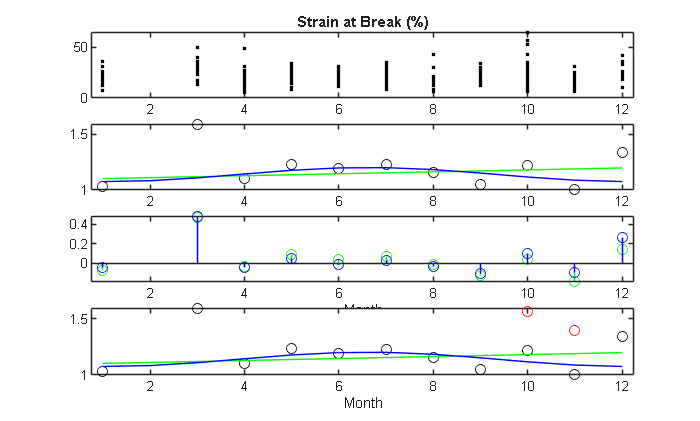

scatter(month_all,all,'marker','.','MarkerEdgeColor','black')
% simple_violin_scatter(month_all, all, 1, 0.5,{'marker','.','MarkerEdgeColor','black'})
hold on
% violinplot(month_all, all,'FaceColor', 'black')
xlim([0.75 12.25])
title(Title)
box on
hold off

subplot(4,1,2); 

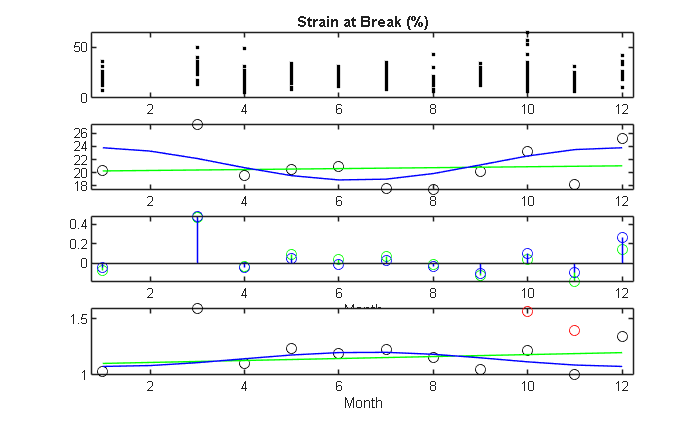

scatter(month,avg,'Marker','o','MarkerEdgeColor','black')
hold on
plot(month, linear_fit, 'Color', 'g');
plot(month, sine_fit, 'Color', 'b');
xlim([0.75 12.25])
box on
hold off

subplot(4,1,3);

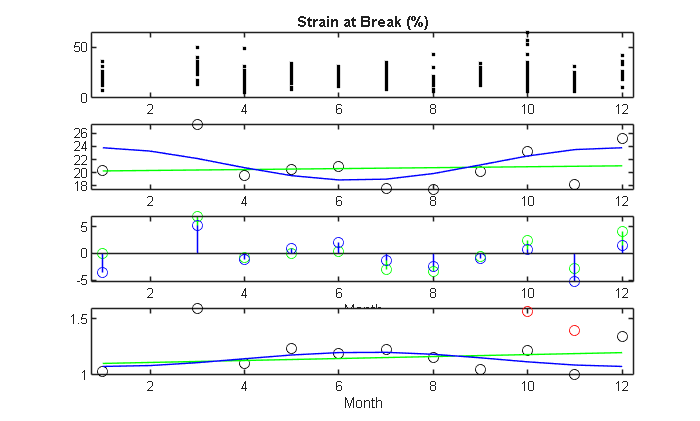

stem(month,linear_residual, 'Color', 'g')
hold on
stem(month,sine_residual, 'Color', 'b')
yline(0)
xlim([0.75 12.25])
xlabel('Month')
box on
hold off

subplot(4,1,4); 

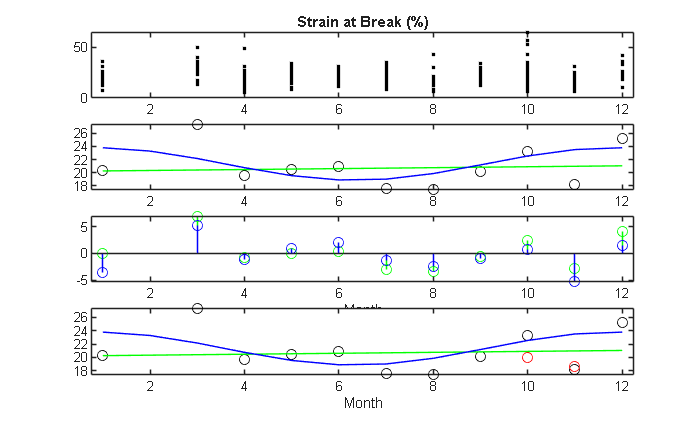

scatter(month,avg,'Marker','o','MarkerEdgeColor','black')
hold on
scatter(month_Aus,avg_aus,'Marker','o','MarkerEdgeColor','red')
plot(month, linear_fit, 'Color', 'g');
plot(month, sine_fit, 'Color', 'b');
xlim([0.75 12.25])
xlabel('Month')
box on
hold off	

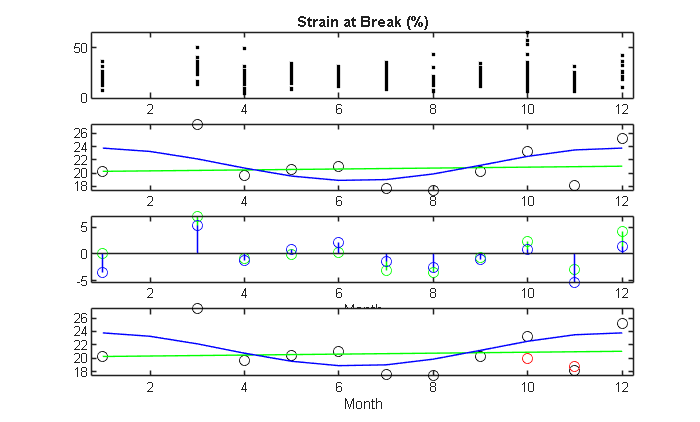

% onepercent

a = -0.7418;
b = 230.28;
r = 4.0127;
s = -0.7089;
t = 225.43;

Title = '1% weight loss (^\circ C)';
all = onepercent_all;
avg = onepercent_avg;
avg_aus = onepercent_avg_Aus;

				
linear_fit = a * month + b;
sine_fit = r * sin(0.5712*month+s)+t;

linear_residual = avg - linear_fit;
sine_residual = avg - sine_fit;


%% PLOT 
subplot(4,1,1);

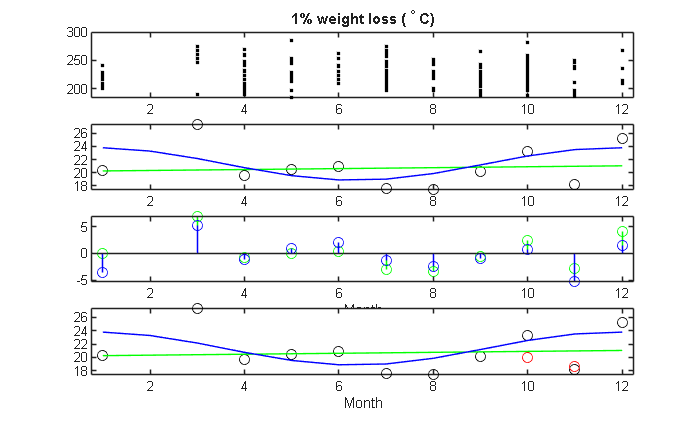

scatter(month_all,all,'marker','.','MarkerEdgeColor','black')
% simple_violin_scatter(month_all, all, 1, 0.5,{'marker','.','MarkerEdgeColor','black'})
hold on
% violinplot(month_all, all,'FaceColor', 'black')
xlim([0.75 12.25])
title(Title)
box on
hold off

subplot(4,1,2); 

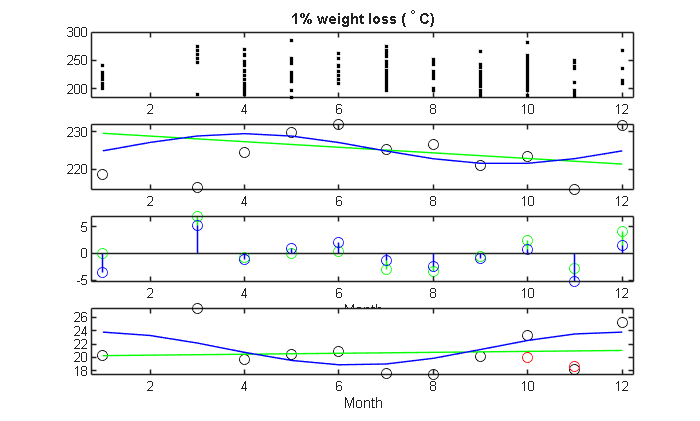

scatter(month,avg,'Marker','o','MarkerEdgeColor','black')
hold on
plot(month, linear_fit, 'Color', 'g');
plot(month, sine_fit, 'Color', 'b');
xlim([0.75 12.25])
box on
hold off

subplot(4,1,3);

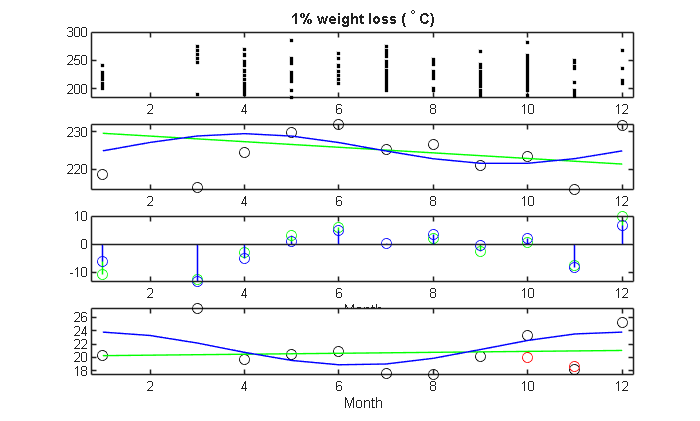

stem(month,linear_residual, 'Color', 'g')
hold on
stem(month,sine_residual, 'Color', 'b')
yline(0)
xlim([0.75 12.25])
xlabel('Month')
box on
hold off		

subplot(4,1,4); 

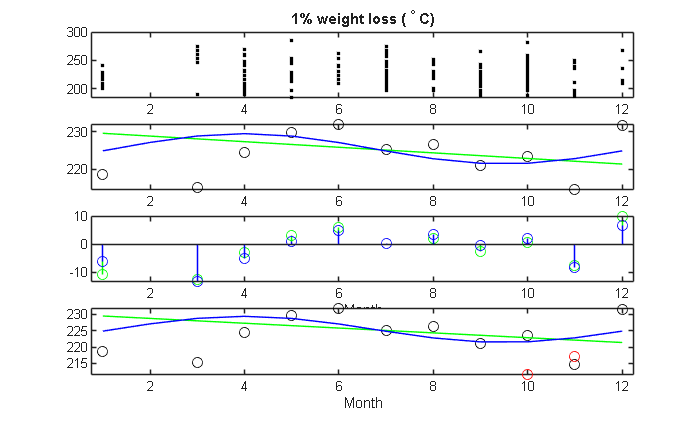

scatter(month,avg,'Marker','o','MarkerEdgeColor','black')
hold on
scatter(month_Aus,avg_aus,'Marker','o','MarkerEdgeColor','red')
plot(month, linear_fit, 'Color', 'g');
plot(month, sine_fit, 'Color', 'b');
xlim([0.75 12.25])
xlabel('Month')
box on
hold off

% fivepercent

a = -0.3821;
b = 279.21;
r = 1.1924;
s = 35.969;
t = 276.19;

Title = '5% weight loss (^\circ C)';
all = fivepercent_all;
avg = fivepercent_avg;
avg_aus = fivepercent_avg_Aus;
				
linear_fit = a * month + b;
sine_fit = r * sin(0.5712*month+s)+t;

linear_residual = avg - linear_fit;
sine_residual = avg - sine_fit;


%% PLOT 
subplot(4,1,1);

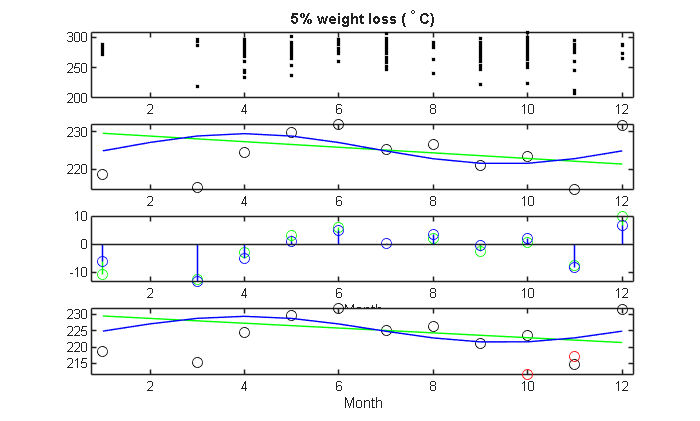

scatter(month_all,all,'marker','.','MarkerEdgeColor','black')
% simple_violin_scatter(month_all, all, 1, 0.5,{'marker','.','MarkerEdgeColor','black'})
hold on
% violinplot(month_all, all,'FaceColor', 'black')
xlim([0.75 12.25])
title(Title)
box on
hold off

subplot(4,1,2); 

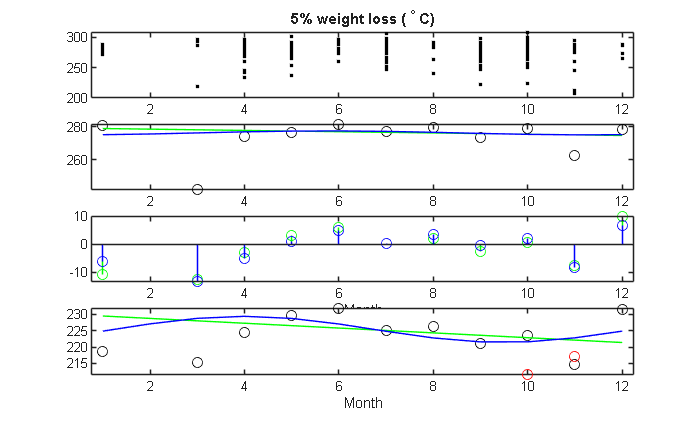

scatter(month,avg,'Marker','o','MarkerEdgeColor','black')
hold on
plot(month, linear_fit, 'Color', 'g');
plot(month, sine_fit, 'Color', 'b');
xlim([0.75 12.25])
box on
hold off

subplot(4,1,3);

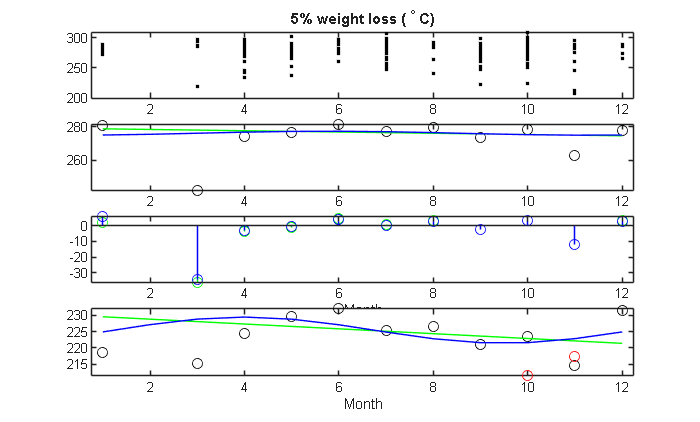

stem(month,linear_residual, 'Color', 'g')
hold on
stem(month,sine_residual, 'Color', 'b')
yline(0)
xlim([0.75 12.25])
xlabel('Month')
box on
hold off		

subplot(4,1,4); 

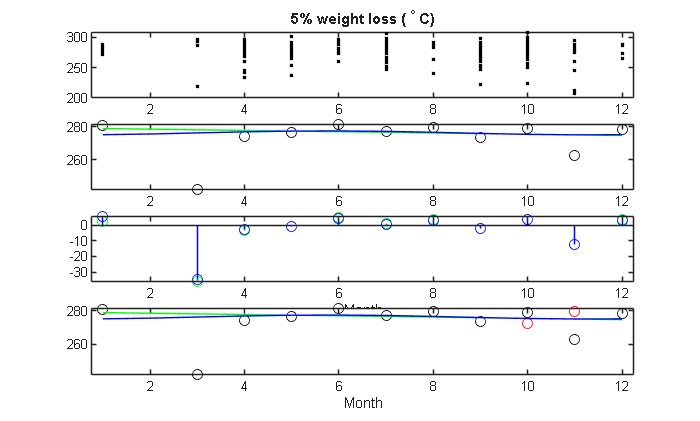

scatter(month,avg,'Marker','o','MarkerEdgeColor','black')
hold on
scatter(month_Aus,avg_aus,'Marker','o','MarkerEdgeColor','red')
plot(month, linear_fit, 'Color', 'g');
plot(month, sine_fit, 'Color', 'b');
xlim([0.75 12.25])
xlabel('Month')
box on
hold off

% tenpercent

a = -0.1212;
b = 299.44;
r = -0.5762;
s = -19.367;
t = 298.42;

Title = '10% weight loss (^\circ C)';
all = tenpercent_all;
avg = tenpercent_avg;
avg_aus = tenpercent_avg_Aus;

				
linear_fit = a * month + b;
sine_fit = r * sin(0.5712*month+s)+t;

linear_residual = avg - linear_fit;
sine_residual = avg - sine_fit;


%% PLOT 
subplot(4,1,1);

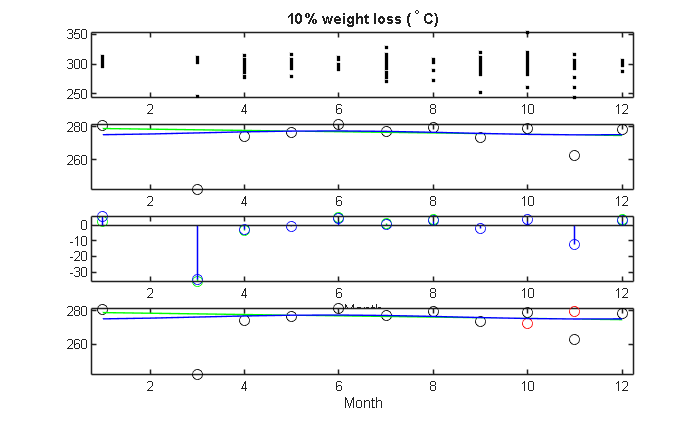

scatter(month_all,all,'marker','.','MarkerEdgeColor','black')
% simple_violin_scatter(month_all, all, 1, 0.5,{'marker','.','MarkerEdgeColor','black'})
hold on
% violinplot(month_all, all,'FaceColor', 'black')
xlim([0.75 12.25])
title(Title)
box on
hold off

subplot(4,1,2); 

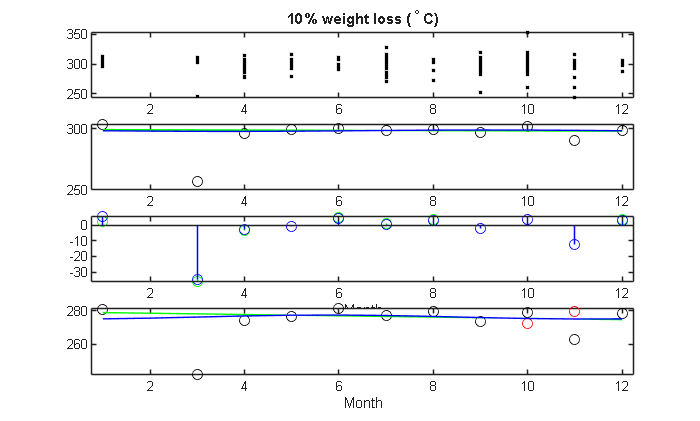

scatter(month,avg,'Marker','o','MarkerEdgeColor','black')
hold on
plot(month, linear_fit, 'Color', 'g');
plot(month, sine_fit, 'Color', 'b');
xlim([0.75 12.25])
box on
hold off

subplot(4,1,3);

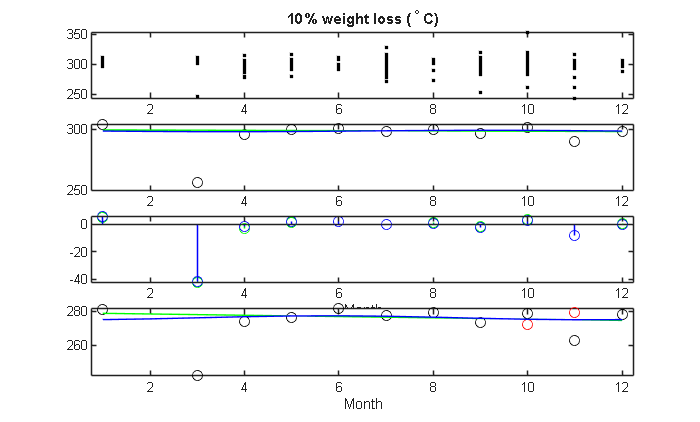

stem(month,linear_residual, 'Color', 'g')
hold on
stem(month,sine_residual, 'Color', 'b')
yline(0)
xlim([0.75 12.25])
xlabel('Month')
box on
hold off		

subplot(4,1,4); 

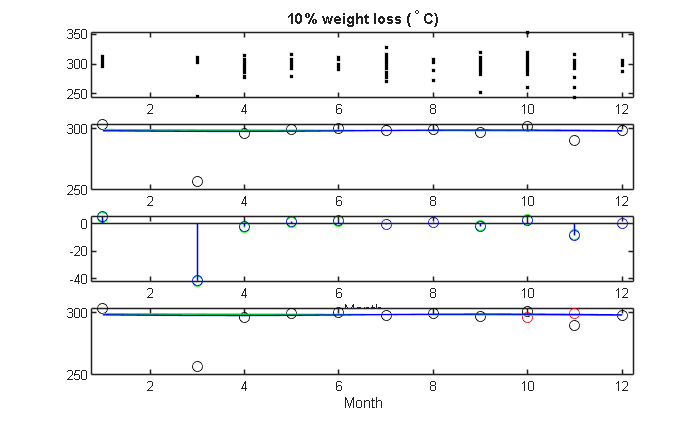

scatter(month,avg,'Marker','o','MarkerEdgeColor','black')
hold on
scatter(month_Aus,avg_aus,'Marker','o','MarkerEdgeColor','red')
plot(month, linear_fit, 'Color', 'g');
plot(month, sine_fit, 'Color', 'b');
xlim([0.75 12.25])
xlabel('Month')
box on
hold off

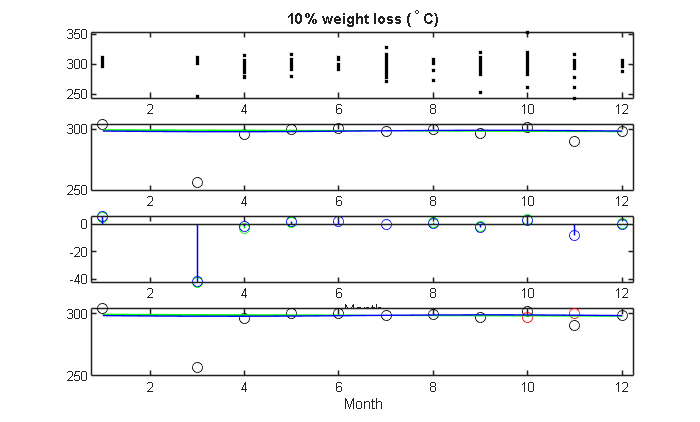

% crystallinity

a = 1.0719;
b = 11.42;
r = -4.93;
s = -0.6597;
t = 18.55;

Title = 'Degree of Crystallinity (%)';
all = crystallinity_all;
avg = crystallinity_avg;
avg_aus = crystallinity_avg_Aus;
				
linear_fit = a * month + b;
sine_fit = r * sin(0.5712*month+s)+t;

linear_residual = avg - linear_fit;
sine_residual = avg - sine_fit;


%% PLOT 
subplot(4,1,1);

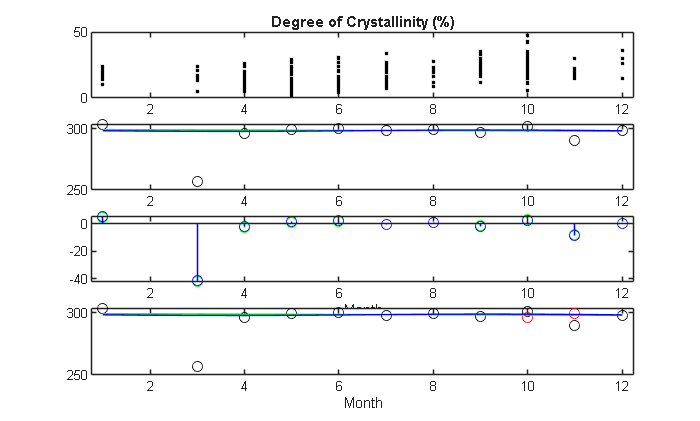

scatter(month_all,all,'marker','.','MarkerEdgeColor','black','ColorVariable','country_all')
% simple_violin_scatter(month_all, all, 1, 0.5,{'marker','.','MarkerEdgeColor','black'})
hold on
% violinplot(month_all, all,'FaceColor', 'black')
xlim([0.75 12.25])
title(Title)
box on
hold off

subplot(4,1,2); 

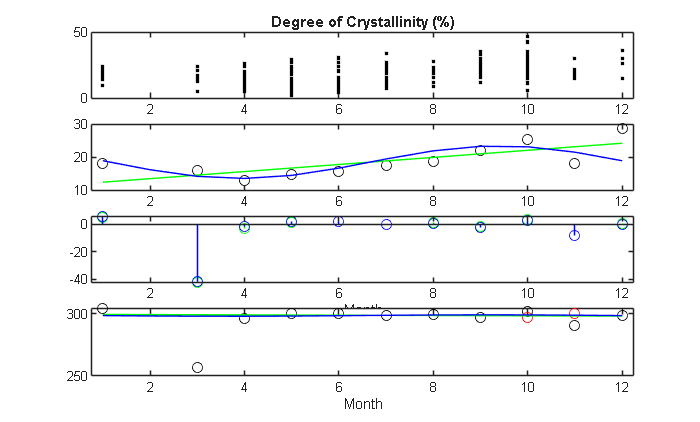

scatter(month,avg,'Marker','o','MarkerEdgeColor','black')
hold on
plot(month, linear_fit, 'Color', 'g');
plot(month, sine_fit, 'Color', 'b');
xlim([0.75 12.25])
box on
hold off

subplot(4,1,3);

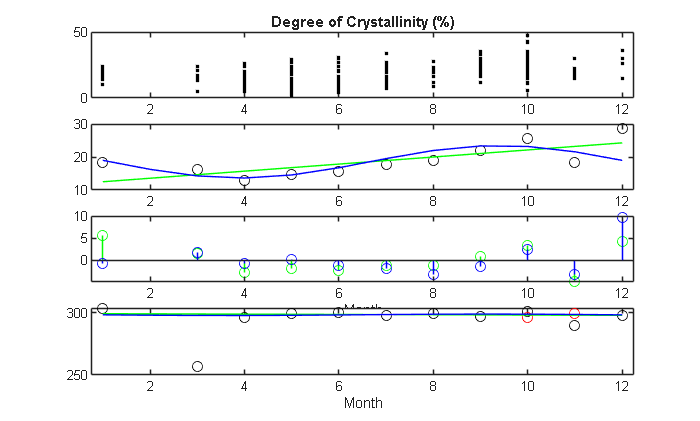

stem(month,linear_residual, 'Color', 'g')
hold on
stem(month,sine_residual, 'Color', 'b')
yline(0)
xlim([0.75 12.25])
xlabel('Month')
box on
hold off		

subplot(4,1,4); 

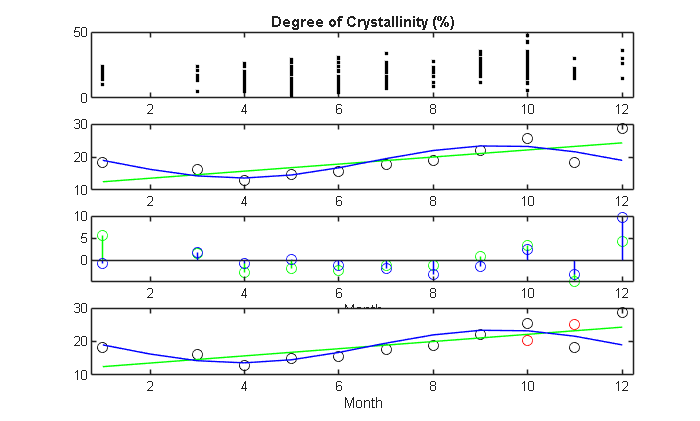

scatter(month,avg,'Marker','o','MarkerEdgeColor','black')
hold on
scatter(month_Aus,avg_aus,'Marker','o','MarkerEdgeColor','red')
plot(month, linear_fit, 'Color', 'g');
plot(month, sine_fit, 'Color', 'b');
xlim([0.75 12.25])
xlabel('Month')
box on
hold off

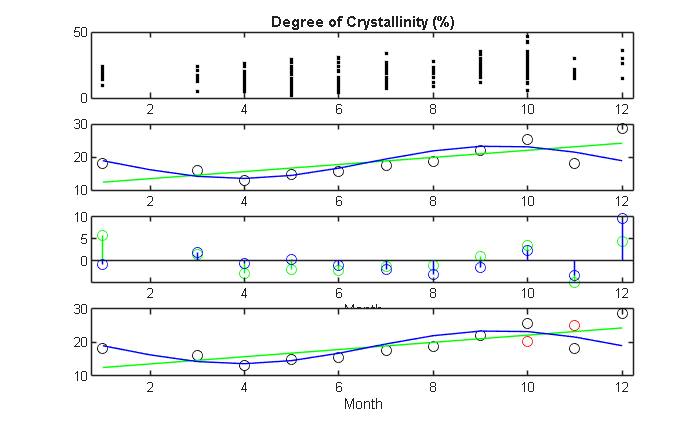

% birefringence

a = -0.054;
b = 46.273;
r = -1.6995;
s = 4.0655;
t = 46.349;

Title = 'Birefringence (\times 10^{-3})';
all = birefringence_all;
avg = birefringence_avg;
avg_aus = birefringence_avg_Aus;

				
linear_fit = a * month + b;
sine_fit = r * sin(0.5712*month+s)+t;

linear_residual = avg - linear_fit;
sine_residual = avg - sine_fit;


%% PLOT 
subplot(4,1,1);

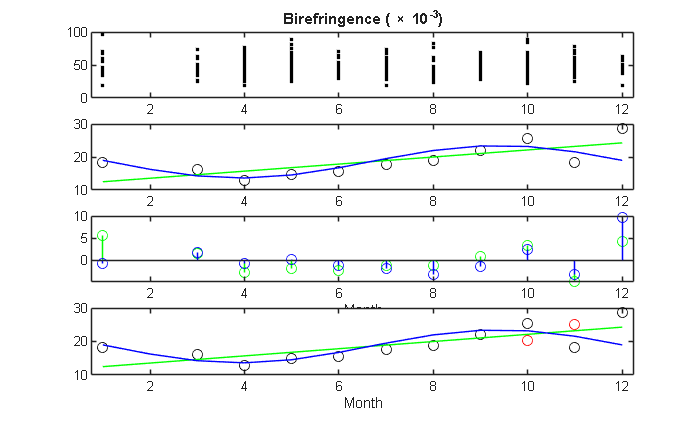

scatter(month_all,all,'marker','.','MarkerEdgeColor','black')
% simple_violin_scatter(month_all, all, 1, 0.5,{'marker','.','MarkerEdgeColor','black'})
hold on
% violinplot(month_all, all,'FaceColor', 'black')
xlim([0.75 12.25])
title(Title)
box on
hold off

subplot(4,1,2); 

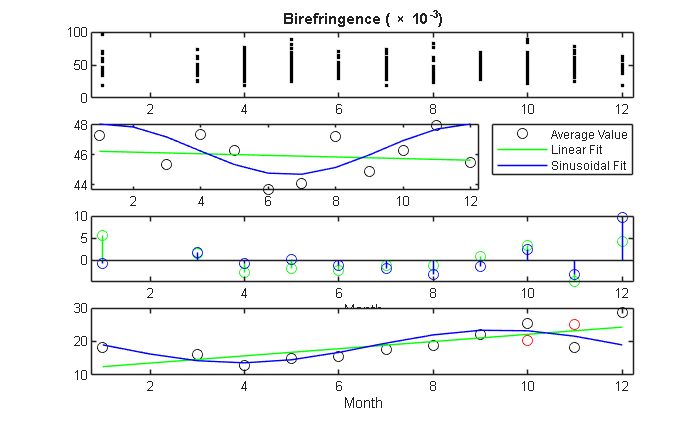

scatter(month,avg,'Marker','o','MarkerEdgeColor','black')
hold on
plot(month, linear_fit, 'Color', 'g');
plot(month, sine_fit, 'Color', 'b');
xlim([0.75 12.25])
legend('Average Value','Linear Fit','Sinusoidal Fit','Location','bestoutside')
box on
hold off

subplot(4,1,3);

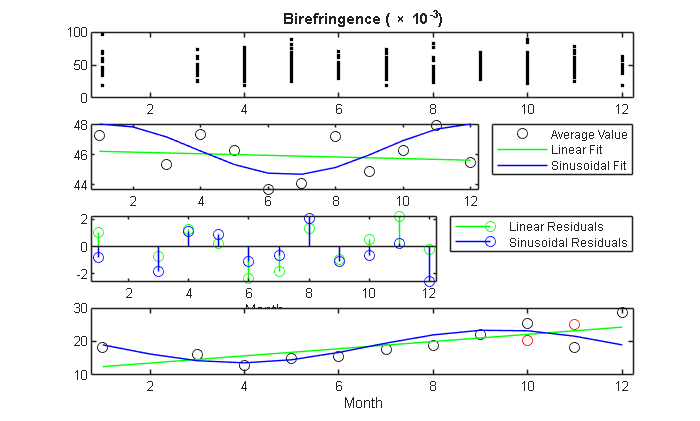

stem(month,linear_residual, 'Color', 'g')
hold on
stem(month,sine_residual, 'Color', 'b')
yline(0)
xlim([0.75 12.25])
xlabel('Month')
legend('Linear Residuals','Sinusoidal Residuals','Location','bestoutside')
box on
hold off		

subplot(4,1,4); 

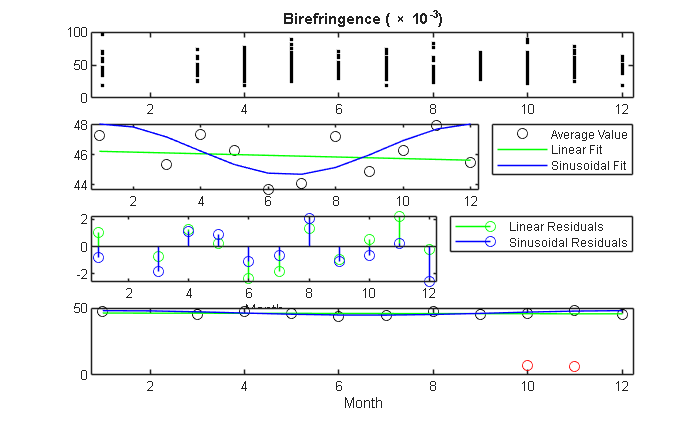

scatter(month,avg,'Marker','o','MarkerEdgeColor','black')
hold on
scatter(month_Aus,avg_aus,'Marker','o','MarkerEdgeColor','red')
plot(month, linear_fit, 'Color', 'g');
plot(month, sine_fit, 'Color', 'b');
xlim([0.75 12.25])
xlabel('Month')
box on
hold off

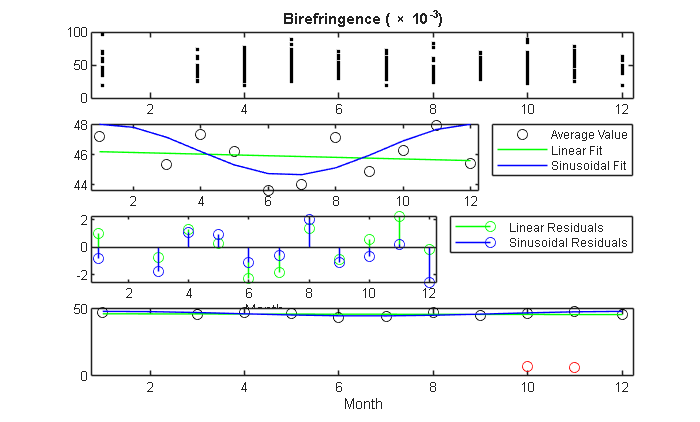

% diameter

a = 0.037;
b = 1.166;
r = 0.1969;
s = -10.31;
t = 1.4278;

Title = 'Diameter (\mu M)';
all = diameter_all;
avg = diameter_avg;
avg_aus = diameter_avg_Aus;

				
linear_fit = a * month + b;
sine_fit = r * sin(0.5712*month+s)+t;

linear_residual = avg - linear_fit;
sine_residual = avg - sine_fit;


%% PLOT 
subplot(4,1,1);

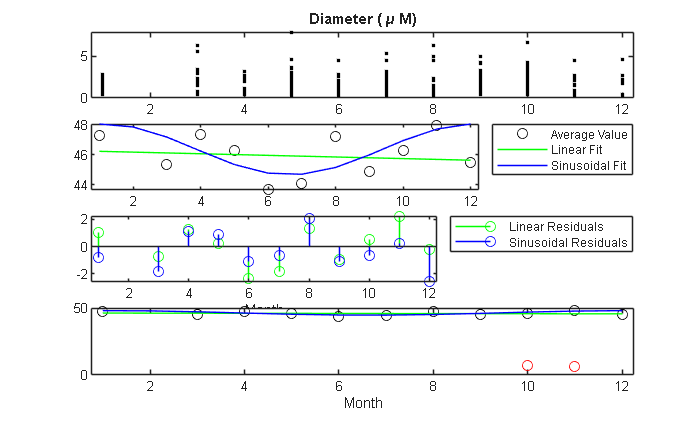

scatter(month_all,all,'marker','.','MarkerEdgeColor','black')
% simple_violin_scatter(month_all, all, 1, 0.5,{'marker','.','MarkerEdgeColor','black'})
hold on
% violinplot(month_all, all,'FaceColor', 'black')
xlim([0.75 12.25])
title(Title)
box on
hold off

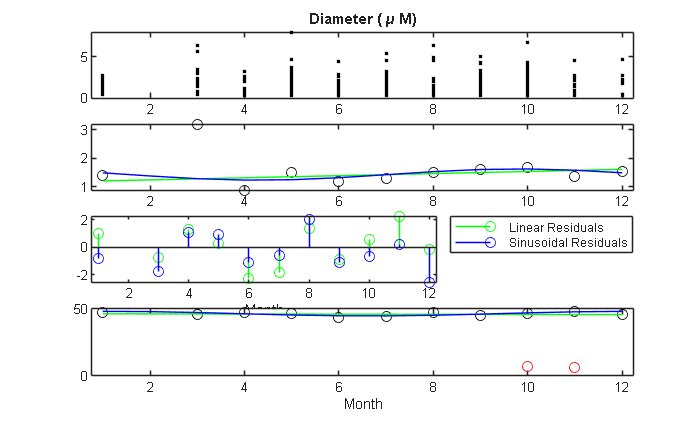


subplot(4,1,2); 
scatter(month,avg,'Marker','o','MarkerEdgeColor','black')
hold on
plot(month, linear_fit, 'Color', 'g');
plot(month, sine_fit, 'Color', 'b');
xlim([0.75 12.25])
box on
hold off

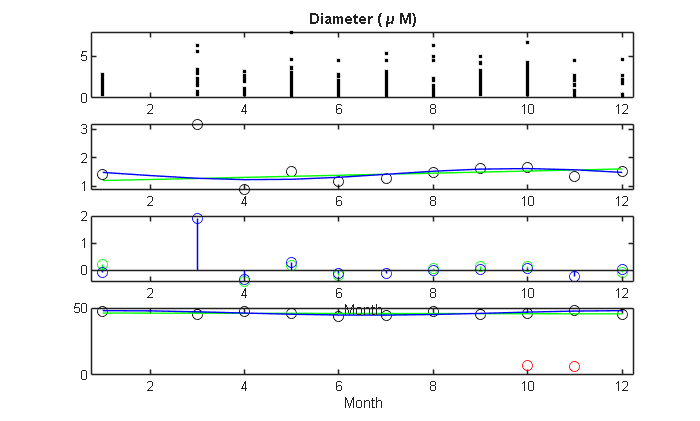


subplot(4,1,3);
stem(month,linear_residual, 'Color', 'g')
hold on
stem(month,sine_residual, 'Color', 'b')
yline(0)
xlim([0.75 12.25])
xlabel('Month')
box on
hold off		

subplot(4,1,4); 

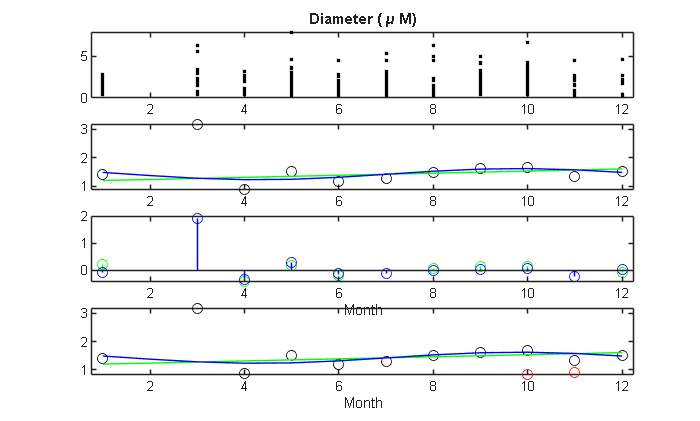

scatter(month,avg,'Marker','o','MarkerEdgeColor','black')
hold on
scatter(month_Aus,avg_aus,'Marker','o','MarkerEdgeColor','red')
plot(month, linear_fit, 'Color', 'g');
plot(month, sine_fit, 'Color', 'b');
xlim([0.75 12.25])
xlabel('Month')
box on
hold off

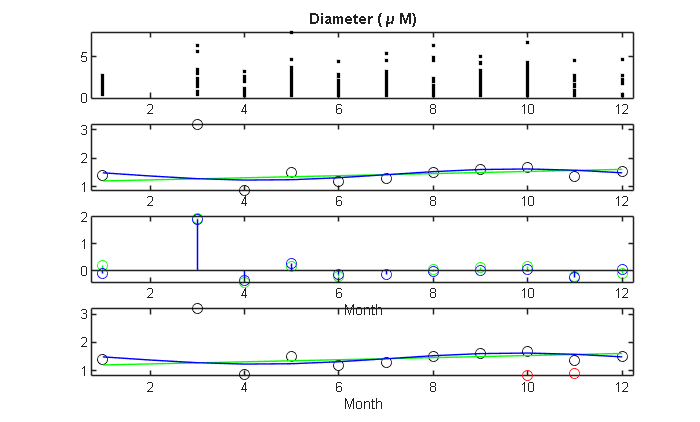

% watercontent

a = -0.1458;
b = 8.1048;
r = 0.9073;
s = -1.112;
t = 7.0491;

Title = 'Water content (%)';
all = watercontent_all;
avg = watercontent_avg;
avg_aus = watercontent_avg_Aus;

				
linear_fit = a * month + b;
sine_fit = r * sin(0.5712*month+s)+t;

linear_residual = avg - linear_fit;
sine_residual = avg - sine_fit;


%% PLOT 
subplot(4,1,1);

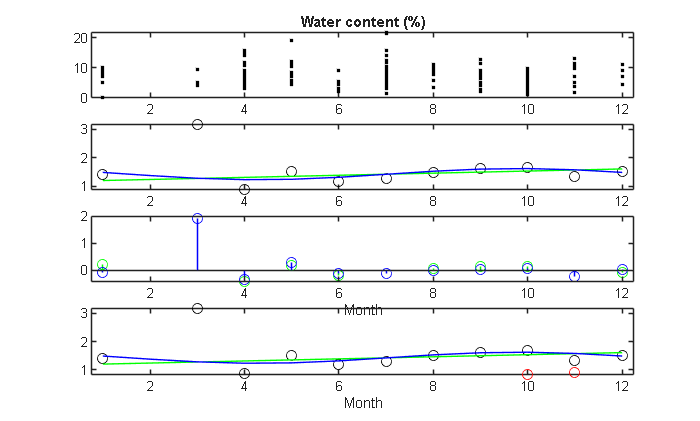

scatter(month_all,all,'marker','.','MarkerEdgeColor','black')
% simple_violin_scatter(month_all, all, 1, 0.5,{'marker','.','MarkerEdgeColor','black'})
hold on
% violinplot(month_all, all,'FaceColor', 'black')
xlim([0.75 12.25])
title(Title)
box on
hold off

subplot(4,1,2); 

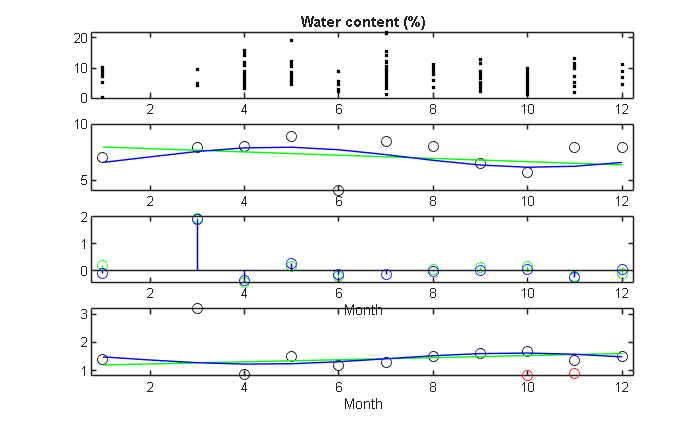

scatter(month,avg,'Marker','o','MarkerEdgeColor','black')
hold on
plot(month, linear_fit, 'Color', 'g');
plot(month, sine_fit, 'Color', 'b');
xlim([0.75 12.25])
box on
hold off

subplot(4,1,3);

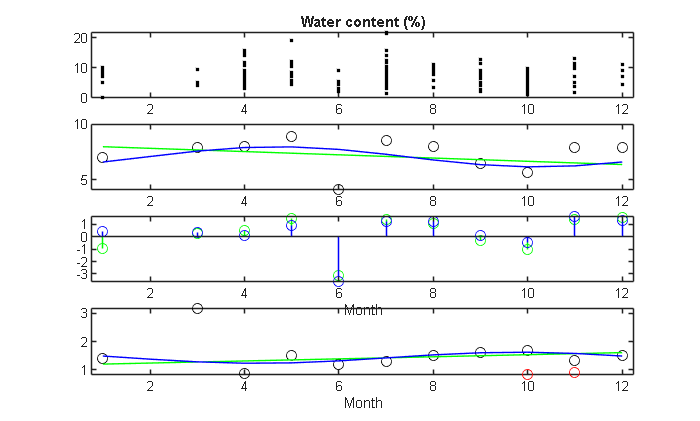

stem(month,linear_residual, 'Color', 'g')
hold on
stem(month,sine_residual, 'Color', 'b')
yline(0)
xlim([0.75 12.25])
xlabel('Month')
box on
hold off		

subplot(4,1,4); 

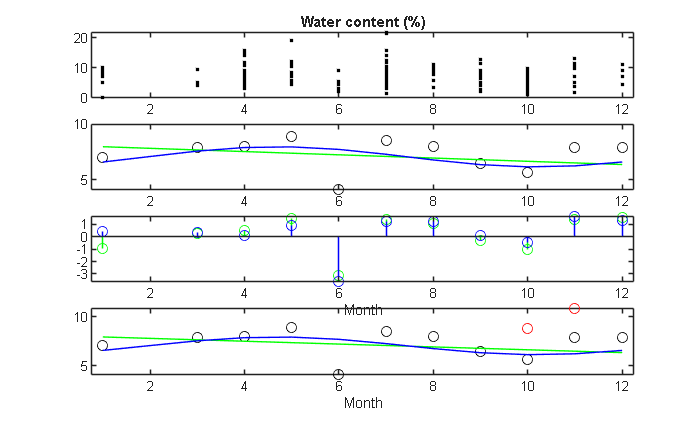

scatter(month,avg,'Marker','o','MarkerEdgeColor','black')
hold on
scatter(month_Aus,avg_aus,'Marker','o','MarkerEdgeColor','red')
plot(month, linear_fit, 'Color', 'g');
plot(month, sine_fit, 'Color', 'b');
xlim([0.75 12.25])
xlabel('Month')
box on
hold off

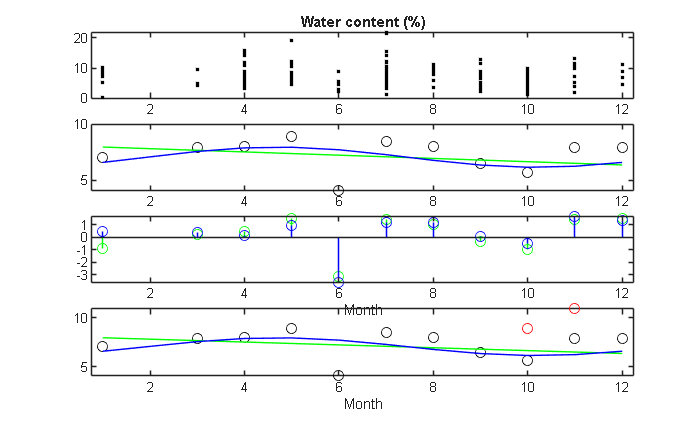

% supercontraction

a = 0.4803;
b = 26.03;
r = -5.4368;
s = 0.907;
t = 28.753;

Title = 'Supercontraction (%)';
all = supercontraction_all;
avg = supercontraction_avg;
avg_aus = supercontraction_avg_Aus;

				
linear_fit = a * month + b;
sine_fit = r * sin(0.5712*month+s)+t;

linear_residual = avg - linear_fit;
sine_residual = avg - sine_fit;


%% PLOT 
subplot(4,1,1);

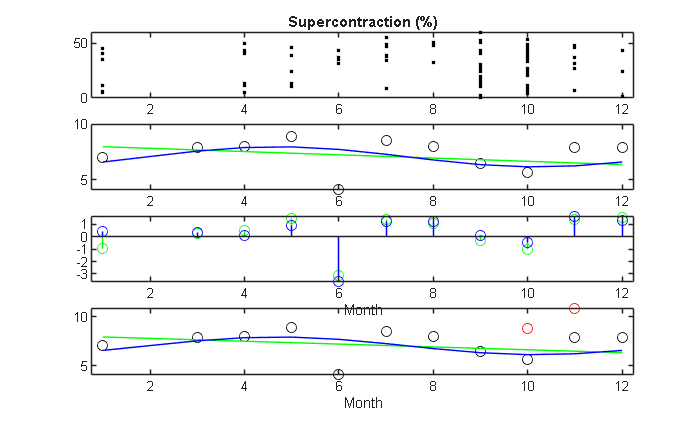

scatter(month_all,all,'marker','.','MarkerEdgeColor','black')
% simple_violin_scatter(month_all, all, 1, 0.5,{'marker','.','MarkerEdgeColor','black'})
hold on
% violinplot(month_all, all,'FaceColor', 'black')
xlim([0.75 12.25])
title(Title)
box on
hold off

subplot(4,1,2); 

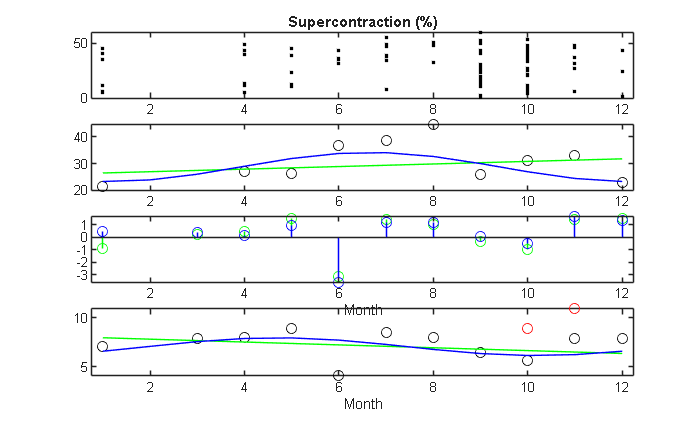

scatter(month,avg,'Marker','o','MarkerEdgeColor','black')
hold on
plot(month, linear_fit, 'Color', 'g');
plot(month, sine_fit, 'Color', 'b');
xlim([0.75 12.25])
box on
hold off

subplot(4,1,3);

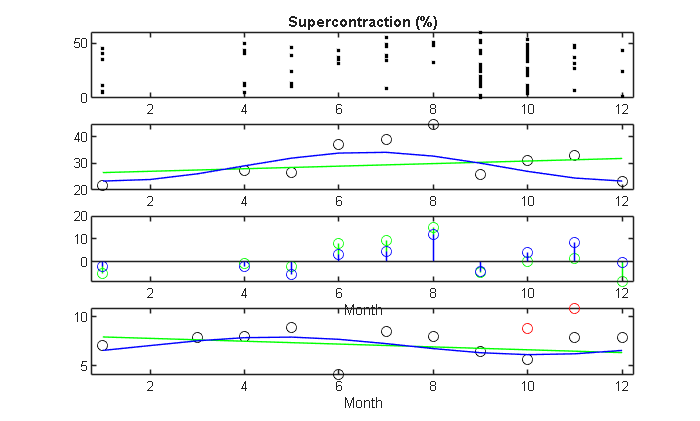

stem(month,linear_residual, 'Color', 'g')
hold on
stem(month,sine_residual, 'Color', 'b')
yline(0)
xlim([0.75 12.25])
xlabel('Month')
box on
hold off	

subplot(4,1,4); 

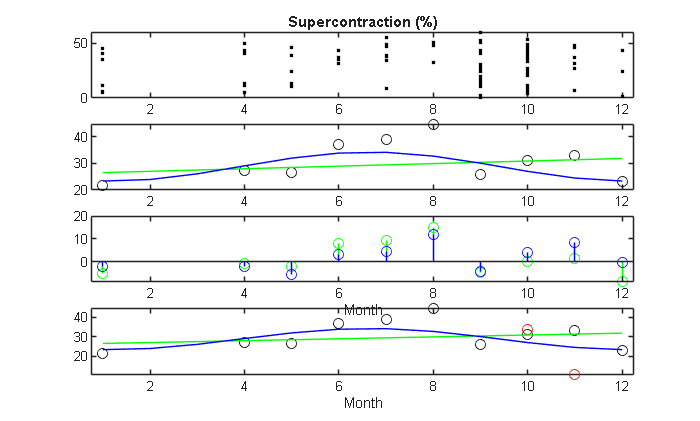

scatter(month,avg,'Marker','o','MarkerEdgeColor','black')
hold on
scatter(month_Aus,avg_aus,'Marker','o','MarkerEdgeColor','red')
plot(month, linear_fit, 'Color', 'g');
plot(month, sine_fit, 'Color', 'b');
xlim([0.75 12.25])
xlabel('Month')
box on
hold off